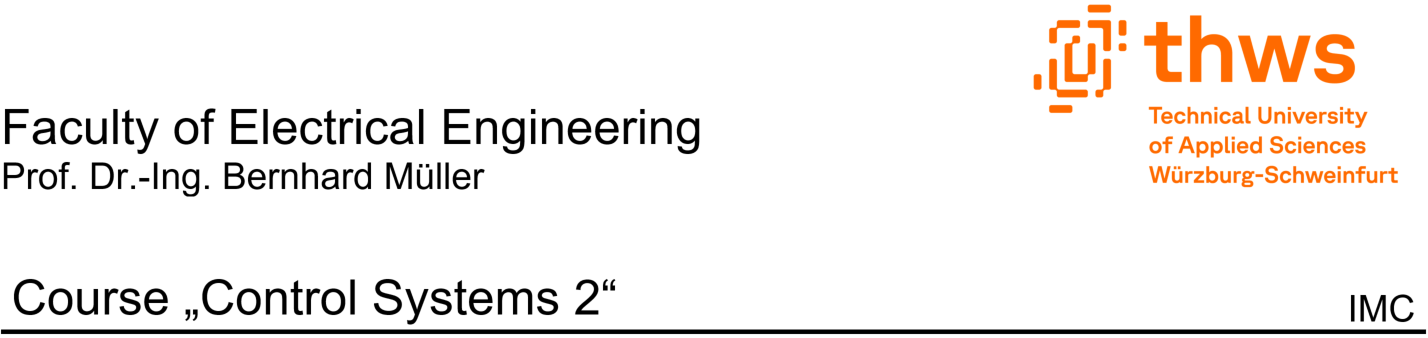

# **Mathematical Modelling and State Equations of Example System "Vehicle-on-ramp"**

In this document a mathematical model for the "vehicle-on-ramp" system illustrated below is derived and expressed in form of nonlinear state equations. To this end, Lagrange's approach for modelling mechanical systems is applied (see e.g. [1]). The vehicle, which moves on an inclined ramp, consists of two parts: a cart moving on frictionless wheels and a cylindrical drive unit with a motor.  Both parts can be modelled as rigid bodies which are connected by a coupling element whose behavior is described by a linear spring equation.

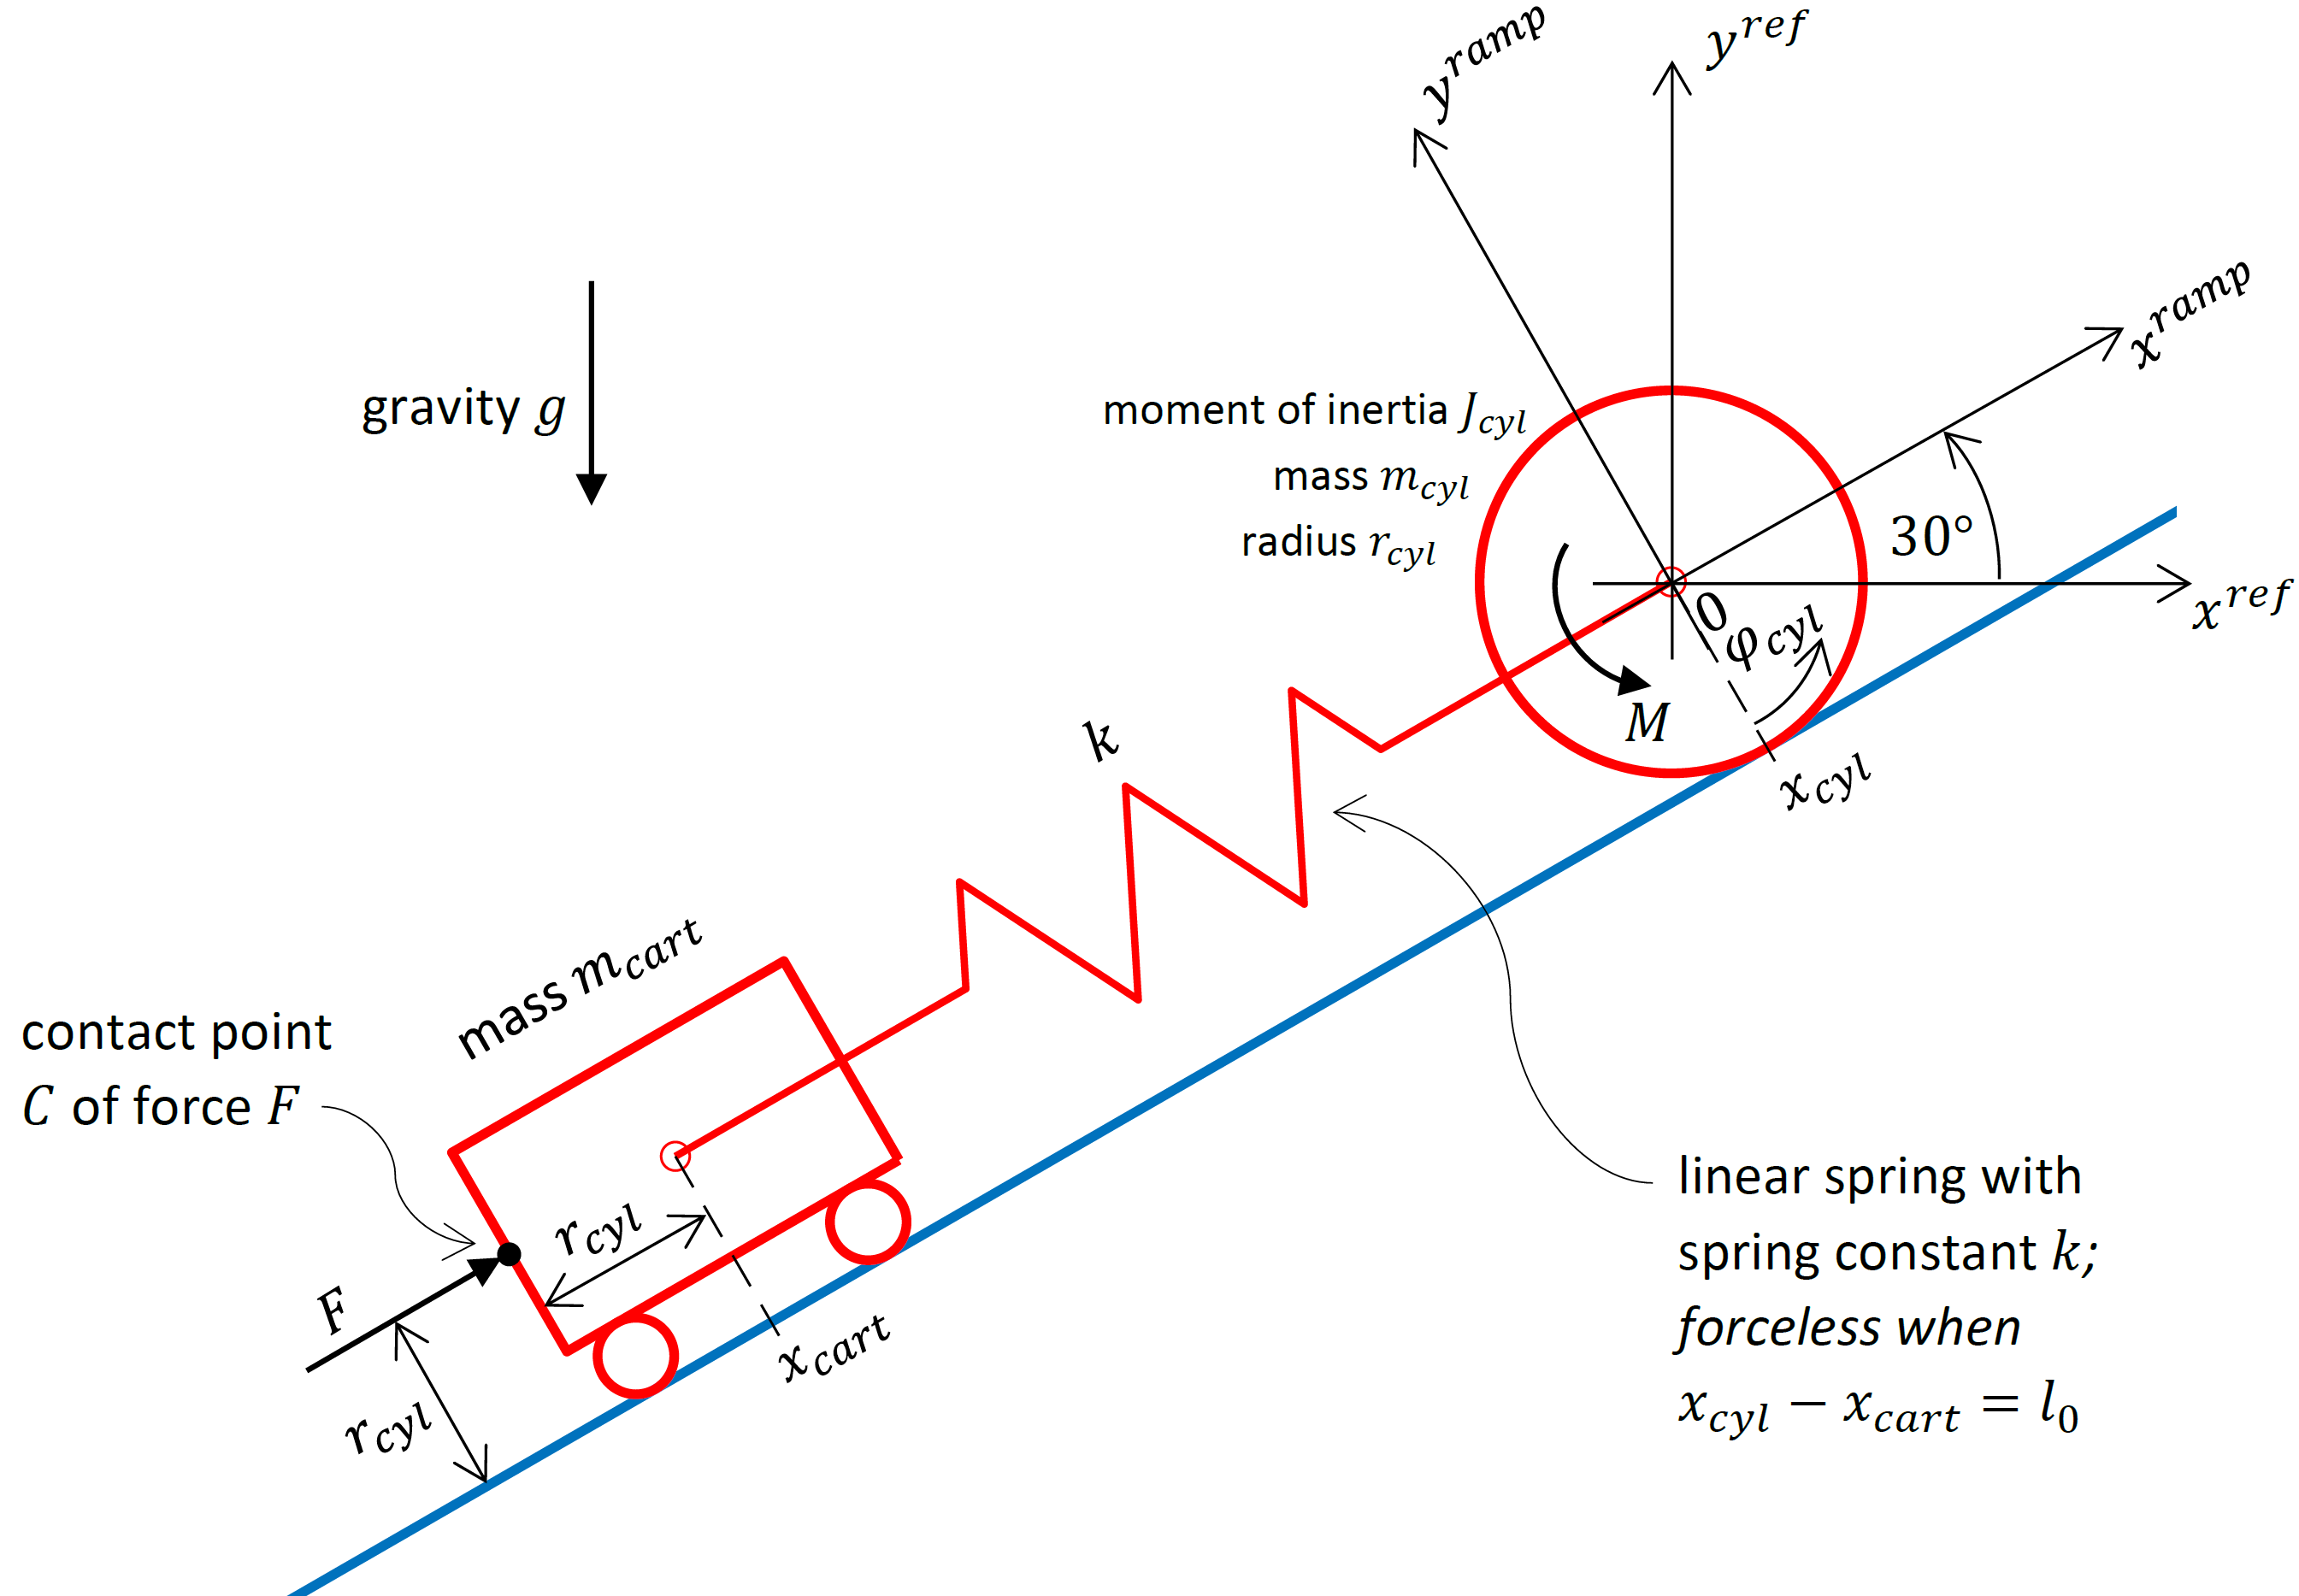  

## Definitions and Variable Declarations

clc;                                    % clear display
clearvars;                              % reset variables

#### System description and definition of important quantities

The schematic diagram above defines coordinate systems and counting directions of important quantities. In particular, the figure introduces the fixed Cartesian reference frame $\left(x^{\textrm{ref}} ,y^{\textrm{ref}} \right)$ and the ramp-fixed coordinate system $\left(x^{\textrm{ramp}} ,y^{\textrm{ramp}} \right)$ which is rotated by the constant angle $30\degree$ with respect to the reference frame. Output variables are the positions $x_{\textrm{cyl}} \left(t\right)$ and $x_{\textrm{cart}} \left(t\right)$ of both vehicle parts on the ramp, i.e. the $x$-positions of their centers of mass in ramp-coordinates. The drive unit is modelled as one single cylindrical rigid body which rolls on the ramp without slipping. The angular position of this cylinder $\varphi {\;}_{\textrm{cyl}} \left(t\right)$ is zero at the point $x_{\textrm{cyl}} =0$. By means of an electric motor, which is of no further interest, the torque $M\left(t\right)$ can be applied to the cylindrical drive unit, i.e. $M\left(t\right)$ represents the control input $u\left(t\right)$. A force $F\left(t\right)$ acting on the cart must be taken into account as disturbance input $z\left(t\right)$. The linear spring is in forceless state if the drive unit and the cart are at the distance $l_0 >0$ to each other, i.e. if $x_{\textrm{cyl}} \left(t\right)-x_{\textrm{cart}} \left(t\right)=l_0$. The spring constant is described by the constant parameter $k>0$. The masses and moments of inertia of the cart's wheels as well as the mass of the spring are neclected. Friction forces and/or torques are not considered (except for the constraint force, which ensures the ideal rolling of the cylindrical drive unit on the ramp). The meaning of some other parameters and quantities of interest is described by the comments in the following variable declaration.

#### **Declare symbolic variables**

syms phi_cyl(t)                         % angular position of drive unit 
syms x_cart(t)                          % position of the cart on the ramp 
                                        % (in ramp coordinate system)
syms M(t)                               % motor torque acting on drive unit
syms F(t)                               % disturbance force acting on cart
syms r_cyl                              % radius of drive unit cylinder
syms J_cyl                              % moment of inertia of drive unit cylinder 
                                        % with respect to its symmetry axis
syms m_cyl                              % mass of drive unit cylinder
syms m_cart                             % mass of cart
syms k                                  % spring constant
syms l_0                                % distance between drive unit and cart 
                                        % where spring is forceless
syms g                                  % gravity of earth
syms q1(t) q2(t)                        % generalized coordinates
syms x1(t) x2(t) x3(t) x4(t) u(t) z(t)  % state variables x, control input u, 
                                        % disturbance input z
syms x1dot x2dot x3dot x4dot            % auxiliary variables needed to express the 
                                        % state differential equations

## **Specify Generalized Coordinates**

It is obvious that the position and orientation of the drive unit and the cart are completely defined if both $x_{\textrm{cart}}$ and $\varphi_{\textrm{cyl}}$ are known. Thus, the system has two degrees of freedom and the generalized coordinates can be defined as:

x_cart=q1

$$x\_cart(t) = q_{1}\left(t\right)$$

phi_cyl=q2

$$phi\_cyl(t) = q_{2}\left(t\right)$$

## **Determine Total Kinetic Energy of the System**

The "vehicle-on-ramp" system consists of two rigid bodies: the cylindrical drive unit and the cart. Consequently, the total kinetic energy can be expressed as the sum of the kinetic energy of the drive unit and the kinetic energy of the cart:


$$T=T_{\textrm{cyl}} +T_{\textrm{cart}}$$


### **Kinetic energy of the cylindrical drive unit**

The overall motion of the cylindrical drive unit is rather complex, since it simultaneously performs a rotational and a translational movement. With respect to its center of mass, however, the kinetic energy of any rigid body can still be stated as a simple sum of a purely translational and a purely rotational movement in relation to a fixed and non-moving reference coordinate system. Thus, the total kinetic energy of the cylindrical drive unit $T_{\textrm{cyl}}$ can be calculated as


$$T_{\textrm{cyl}} =\frac{1}{2}J_{\textrm{cyl}} {\left|\omega {\;}_{\textrm{cyl}\;}^{\textrm{ref}} \right|}^2 +\frac{1}{2}m_{\textrm{cyl}} {\left|v_{\textrm{cyl}}^{\textrm{ref}} \right|}^2$$


with

$\left|\omega {\;}_{\textrm{cyl}\;}^{\textrm{ref}} \right|$: absolute value of angular cylinder speed around its center of mass with respect to fixed reference coordinate system

$\left|v_{\textrm{cyl}}^{\textrm{ref}} \right|$: absolute value of translational speed at center of mass with respect to fixed reference coordinate system

#### Calculation of the translational speed at the center of mass $\left|v_{\textrm{cyl}}^{\textrm{ref}} \right|$

Relationsship between orientation angle $\varphi_{\textrm{cyl}}$ and $x$-position $x_{\textrm{cyl}}$ in ramp coordinate system:

x_cyl(t)=-r_cyl*phi_cyl(t)

$$x\_cyl(t) = -r_{\mathrm{cyl}}\,q_{2}\left(t\right)$$

Position of the cylinder's center of mass in the fixed Cartesian reference frame as a function of the generalized coordinates:

xref_cyl(t) = x_cyl(t)*cos(pi/6)            % ramp is declined by the angle pi/6 (=30°)

$$xref\_cyl(t) = -\frac{\sqrt{3}\,r_{\mathrm{cyl}}\,q_{2}\left(t\right)}{2}$$

yref_cyl(t) = x_cyl(t)*sin(pi/6)            % ramp is declined by the angle pi/6 (=30°)

$$yref\_cyl(t) = -\frac{r_{\mathrm{cyl}}\,q_{2}\left(t\right)}{2}$$

Absolute value of translational cylinder speed as a function of $q_{1/2}$ and ${\dot{q} }_{1/2}$ with respect to the fixed reference coordinate system:

vref_cyl(t) = simplify(sqrt(diff(xref_cyl(t),t)^2+diff(yref_cyl(t),t)^2))

$$vref\_cyl(t) = \sqrt{{r_{\mathrm{cyl}}}^{2}\,{\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}}$$

#### Calculation of the angular speed around the center of mass $\omega {\;}_{\textrm{cyl}\;}^{\textrm{ref}}$

In case of the "vehicle-on-ramp" system the angular speed vector ${\underline{\omega} }_{\textrm{cyl}}^{\textrm{ref}} \;$describing the rotation of the drive unit is parallel to the $z$-axis at all times such that it can be expressed by its scalar $z$-component $\omega_{\textrm{cyl}}^{\textrm{ref}}$ only. Moreover, since the ramp is neither rotating nor changing its slope, the angular speed of the cylinder modelling the drive unit can simply be calculated as:

omegaref_cyl(t)=diff(phi_cyl(t),t)

$$omegaref\_cyl(t) = \frac{\partial }{\partial t}q_{2}\left(t\right)$$

#### Calculation of the kinetic energy of the cylindrical drive unit $T_{\textrm{cyl}}$

Using the above formula for the kinetic energy expressed with respect to the mass center point finally yields

T_cyl(t)=simplify(1/2*m_cyl*vref_cyl(t)^2+1/2*J_cyl*omegaref_cyl(t)^2)

$$T\_cyl(t) = \frac{\left(m_{\mathrm{cyl}}\,{r_{\mathrm{cyl}}}^{2}+J_{\mathrm{cyl}}\right)\,{\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}}{2}$$

### Kinetic energy of the cart

The cart performs a purely translational movement (see figure above). Thus, the total kinetic energy is given as


$$T_{\textrm{cart}} =\frac{1}{2}m_{\textrm{cart}} {\left|v_{\textrm{cart}}^{\textrm{ref}} \right|}^2$$


where ${\left|v_{\textrm{cart}}^{\textrm{ref}} \right|}^2$denotes the absolute value of the cart's speed with respect to the fixed non-moving reference frame.

#### Calculation of the translational speed at the center of mass $\left|v_{\textrm{cart}}^{\textrm{ref}} \right|$

Position of the cart's center of mass in the fixed Cartesian reference frame as a function of the generalized coordinates:

xref_cart(t) = x_cart(t)*cos(pi/6)      % ramp is declined by the angle pi/6 (=30°)

$$xref\_cart(t) = \frac{\sqrt{3}\,q_{1}\left(t\right)}{2}$$

yref_cart(t) = x_cart(t)*sin(pi/6)      % ramp is declined by the angle pi/6 (=30°)

$$yref\_cart(t) = \frac{q_{1}\left(t\right)}{2}$$

Absolute value of translational cart speed as a function of $q_{1/2}$ and ${\dot{q} }_{1/2}$ with respect to the fixed reference coordinate system:

vref_cart(t) = simplify(sqrt(diff(xref_cart(t),t)^2+diff(yref_cart(t),t)^2))

$$vref\_cart(t) = \sqrt{{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}$$

#### Calculation of the kinetic energy of the cart $T_{\textrm{cart}}$

Using the above formula for the kinetic energy expressed with respect to the mass center point finally yields

T_cart(t)=simplify(1/2*m_cart*vref_cart(t)^2)

$$T\_cart(t) = \frac{m_{\mathrm{cart}}\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{2}$$

### **Total kinetic energy of the system**

The total kinetic energy of the system results from the sum of the kinetic energy of the cylindrical drive unit and of the cart as

T(t)=simplify(T_cyl(t)+T_cart(t))

$$T(t) = \frac{\left(m_{\mathrm{cyl}}\,{r_{\mathrm{cyl}}}^{2}+J_{\mathrm{cyl}}\right)\,{\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}}{2}+\frac{m_{\mathrm{cart}}\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{2}$$

## **Determine Total Potential Energy of the System**

The impact of gravity and of the linear spring can both be expressed using potential energy terms. As the system consists of two rigid bodies, the total potential energy can be calculated as the sum


$$V=V_{\textrm{cyl},g} +V_{\textrm{cart},g} +V_k$$


where the indices "g" and "k" indicate the potential energy due to gravity and due to the spring, respectively. 

#### Gravitational potential energies $V_{\textrm{cyl},g}$ and $V_{\textrm{cart},g}$

Assuming without loss of generality that the potential energy due to gravity is zero at all positions with $y$-coordinate $y=0$ with respect to the Cartesian reference frame, $V_{\textrm{cyl},g}$ and $V_{\textrm{cart},g}$ can be expressed according to

V_cylg(t)=g*m_cyl*yref_cyl(t)

$$V\_cylg(t) = -\frac{g\,m_{\mathrm{cyl}}\,r_{\mathrm{cyl}}\,q_{2}\left(t\right)}{2}$$

V_cartg(t)=g*m_cart*yref_cart(t)

$$V\_cartg(t) = \frac{g\,m_{\mathrm{cart}}\,q_{1}\left(t\right)}{2}$$

####  Potential energy due to the spring $V_k$

In general, the potential energy of a linear spring with spring constant $k$ is given by the formula [2]


$$V_{\textrm{spring}} =\frac{1}{2}ks^2$$


where $s$ denotes the change in length compared to the size of the spring in forceless state. Applying this equation to the "vehicle-on-ramp" system yields

V_k(t)=1/2*k*(x_cyl(t)-x_cart(t)-l_0)^2

$$V\_k(t) = \frac{k\,{\left(l_{0}+q_{1}\left(t\right)+r_{\mathrm{cyl}}\,q_{2}\left(t\right)\right)}^{2}}{2}$$

#### Calculating total potential energy of the system

The total kinetic energy results from the sum of the contributions due to gravity and due to the spring:

V(t)=V_cylg(t)+V_cartg(t)+V_k(t)

$$V(t) = \frac{k\,{\left(l_{0}+q_{1}\left(t\right)+r_{\mathrm{cyl}}\,q_{2}\left(t\right)\right)}^{2}}{2}+\frac{g\,m_{\mathrm{cart}}\,q_{1}\left(t\right)}{2}-\frac{g\,m_{\mathrm{cyl}}\,r_{\mathrm{cyl}}\,q_{2}\left(t\right)}{2}$$

## Lagrangian 

The Lagrangian 


$$L=T-V$$


can now easily be stated as a function of $q_{1/2}$ and ${\dot{q} }_{1/2}$:

L(t) = simplify(T(t) - V(t))

$$L(t) = \frac{\left(m_{\mathrm{cyl}}\,{r_{\mathrm{cyl}}}^{2}+J_{\mathrm{cyl}}\right)\,{\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}}{2}-\frac{k\,{\left(l_{0}+q_{1}\left(t\right)+r_{\mathrm{cyl}}\,q_{2}\left(t\right)\right)}^{2}}{2}+\frac{m_{\mathrm{cart}}\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{2}-\frac{g\,m_{\mathrm{cart}}\,q_{1}\left(t\right)}{2}+\frac{g\,m_{\mathrm{cyl}}\,r_{\mathrm{cyl}}\,q_{2}\left(t\right)}{2}$$

## **Non-conservative Generalized Forces**

In general, the non-conservative generalized forces $Q_{i,\textrm{nc}}$ of a system with $N$ degrees of freedom are given as [1]

$Q_{i,\textrm{nc}} =\left(\sum_{k=1}^K {\underline{F} }_{k,\textrm{nc}}^T \frac{\partial {\underline{v} }_{k\;} }{\partial {\dot{q} }_i }\right)+\left(\sum_{l=1}^L {\underline{M} }_{l,\textrm{nc}}^T \frac{\partial {\underline{\omega} }_{l\;} }{\partial {\dot{q} }_i }\right)$, $i=1,2,\ldotp \ldotp \ldotp ,N$

where ${\underline{F} }_{k,\textrm{nc}}$, $k=1,2,\ldotp \ldotp \ldotp ,K$, and ${\underline{M} }_{l,\textrm{nc}}$, $l=1,2,\ldotp \ldotp \ldotp ,L$, represent all non-constraint and non-conservative force and torque vectors acting on the system and ${\underline{v} }_{k\;}$, $k=1,2,\ldotp \ldotp \ldotp ,K$, as well as ${\underline{\omega} }_{l\;}$, $l=1,2,\ldotp \ldotp \ldotp ,L$, are the speed and angular speed vectors of the corresponding contact points. 

Applied to the "vehicle-on-ramp" system, the number of degrees of freedom is $N=2$ and the external force $F\left(t\right)$ as well as the motor torque $M\left(t\right)$ (see figure above) represent the only non-conservative quantities acting on the mechanics. Thus, expressed in reference coordinates the formula above simplifies to the two non-conservative generalized force terms


$$\begin{array}{l}
Q_{1,\textrm{nc}} ={\left({\underline{F} }^{\textrm{ref}} \right)}^T \frac{\;\partial {\underline{v} }_C^{\textrm{ref}} }{\partial \dot{q_1 } \;\;}+{\left({\underline{M} }^{\textrm{ref}} \right)}^T \frac{\;\partial {\underline{\omega} }_{\textrm{cyl}}^{\textrm{ref}} \;}{\partial \dot{q_1 } }\\
Q_{2,\textrm{nc}} ={\left({\underline{F} }^{\textrm{ref}} \right)}^T \frac{\;\partial {\underline{v} }_C^{\textrm{ref}} }{\partial \dot{q_2 } \;\;}+{\left({\underline{M} }^{\textrm{ref}} \right)}^T \frac{\;\partial {\underline{\omega} }_{\textrm{cyl}}^{\textrm{ref}} \;}{\partial \dot{q_2 } }
\end{array}$$


#### Force vector ${\underline{F} }^{\textrm{ref}\;}$ and corresponding speed vector of the contact point ${\underline{v} }_C^{\textrm{ref}}$ in reference coordinates

In ramp coordinates the force $F\left(t\right)$ acts in positive $x$-direction. Consequently, with respect to the fixed reference coordinate system, the force vector can be expressed as

Fref_vec(t)=F(t)*[cos(pi/6);sin(pi/6);0]

$$Fref\_vec(t) = \left(\begin{array}{c} \frac{\sqrt{3}\,F\left(t\right)}{2}\\ \frac{F\left(t\right)}{2}\\ 0 \end{array}\right)$$

The position of the corresponding contact point $C$ (see figure) of the force $F\left(t\right)$ in ramp coordinates is  

xramp_C(t)=x_cart(t)-r_cyl

$$xramp\_C(t) = q_{1}\left(t\right)-r_{\mathrm{cyl}}$$

Transformed into the fixed Cartesian reference frame, the contact point $C$ is described by

xref_C(t)=xramp_C(t)*cos(pi/6)

$$xref\_C(t) = -\frac{\sqrt{3}\,\left(r_{\mathrm{cyl}}-q_{1}\left(t\right)\right)}{2}$$

yref_C(t)=xramp_C(t)*sin(pi/6)

$$yref\_C(t) = \frac{q_{1}\left(t\right)}{2}-\frac{r_{\mathrm{cyl}}}{2}$$

Calculating the time derivative yields the speed vector ${\underline{v} }_C$ of the contact point $C$ in reference coordinates:

vref_Cvec(t)=[simplify(diff(xref_C(t),t));simplify(diff(yref_C(t),t));0]

$$vref\_Cvec(t) = \left(\begin{array}{c} \frac{\sqrt{3}\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{2}\\ \frac{\frac{\partial }{\partial t}q_{1}\left(t\right)}{2}\\ 0 \end{array}\right)$$

#### Torque vector ${\underline{M} }^{\textrm{ref}\;}$ and corresponding angular speed vector ${\underline{\omega} }_{\textrm{cyl}}^{\textrm{ref}} \;$ in reference coordinates

The motor torque $M\left(t\right)$acts around the $z$-axis which represents the fixed axis of rotation for the cylindrical drive unit. Thus, we can state the associated torque vector according to

Mref_vec(t)=M(t)*[0;0;1]

$$Mref\_vec(t) = \left(\begin{array}{c} 0\\ 0\\ M\left(t\right) \end{array}\right)$$

and the corresponding angular speed vector as

omegaref_cylvec(t)=omegaref_cyl(t)*[0;0;1]

$$omegaref\_cylvec(t) = \left(\begin{array}{c} 0\\ 0\\ \frac{\partial }{\partial t}q_{2}\left(t\right) \end{array}\right)$$

with respect to the Cartesian reference frame and considering the counting directions specified in the figure above.

#### Non-conservative generalized force $Q_{1,\textrm{nc}}$ associated to $q_1$

Evaluating


$$Q_{1,\textrm{nc}} ={\left({\underline{F} }^{\textrm{ref}} \right)}^T \frac{\;\partial {\underline{v} }_C^{\textrm{ref}} }{\partial \dot{q_1 } \;\;}+{\left({\underline{M} }^{\textrm{ref}} \right)}^T \frac{\;\partial {\underline{\omega} }_{\textrm{cyl}}^{\textrm{ref}} \;}{\partial \dot{q_1 } }$$


results in

Q1_nc(t)=simplify(transpose(Fref_vec(t))*(diff(vref_Cvec(t),diff(q1(t),t))) ...
                    + transpose(Mref_vec(t))*(diff(omegaref_cylvec(t),diff(q1(t),t))))

$$Q1\_nc(t) = F\left(t\right)$$

####  Non-conservative generalized force $Q_{2,\textrm{nc}}$ associated to $q_2$

Evaluating


$$Q_{2,\textrm{nc}} ={\left({\underline{F} }^{\textrm{ref}} \right)}^T \frac{\;\partial {\underline{v} }_C^{\textrm{ref}} }{\partial \dot{q_2 } \;\;}+{\left({\underline{M} }^{\textrm{ref}} \right)}^T \frac{\;\partial {\underline{\omega} }_{\textrm{cyl}}^{\textrm{ref}} \;}{\partial \dot{q_2 } }$$


results in

Q2_nc(t)=simplify(transpose(Fref_vec(t))*(diff(vref_Cvec(t),diff(q2(t),t))) ...
                    + transpose(Mref_vec(t))*(diff(omegaref_cylvec(t),diff(q2(t),t))))

$$Q2\_nc(t) = M\left(t\right)$$

## Equations of Motion in Generalized Coordinates

In general, using the Lagrangian $L$ and the non-conservative generalized forces $Q_{i,\textrm{nc}}$, the equations of motion in the generalized coordinates are obtained from the $N$ Lagrange's equations (of 2nd kind)

$\frac{d\;}{\textrm{dt}}\left(\frac{\partial L\;}{\partial {\dot{q} }_i }\right)-\frac{\;\partial L}{\partial q_{i\;} }=Q_{i,\textrm{nc}}$ ,  $i=1,2,\ldotp \ldotp \ldotp ,N$

Applied to the "vehicle-on-ramp" system with two degrees of freedom ($N=2$), the evaluation of


$$\begin{array}{l}
\frac{d\;}{\textrm{dt}}\left(\frac{\partial L\;}{\partial {\dot{q} }_1 }\right)-\frac{\;\partial L}{\partial q_{1\;} }=Q_{1,\textrm{nc}} \\
\frac{d\;}{\textrm{dt}}\left(\frac{\partial L\;}{\partial {\dot{q} }_2 }\right)-\frac{\;\partial L}{\partial q_{2\;} }=Q_{2,\textrm{nc}} 
\end{array}$$


results in the following two differential equations in the generalized coordinates:

deq1=simplify( diff( diff(L(t),diff(q1(t),t)),t ) - diff(L(t),q1(t)) ) == Q1_nc(t)

$$deq1 = m_{\mathrm{cart}}\,\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right)+\frac{g\,m_{\mathrm{cart}}}{2}+\frac{k\,\left(2\,l_{0}+2\,q_{1}\left(t\right)+2\,r_{\mathrm{cyl}}\,q_{2}\left(t\right)\right)}{2}=F\left(t\right)$$

deq2=simplify( diff( diff(L(t),diff(q2(t),t)),t ) - diff(L(t),q2(t)) ) == Q2_nc(t) 

$$deq2 = \left(m_{\mathrm{cyl}}\,{r_{\mathrm{cyl}}}^{2}+J_{\mathrm{cyl}}\right)\,\frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right)+k\,r_{\mathrm{cyl}}\,\left(l_{0}+q_{1}\left(t\right)+r_{\mathrm{cyl}}\,q_{2}\left(t\right)\right)-\frac{g\,m_{\mathrm{cyl}}\,r_{\mathrm{cyl}}}{2}=M\left(t\right)$$

## Derive (Nonlinear) State Equations

#### Define state variables

In order to obtain a state space description of the "vehicle-on-ramp" system from the equations of motion, the generalized coordinates and their first-order time derivatives are introduced as state variables:

x1_def = q1(t) == x1(t)              % x1 --> cart position on ramp

$$x1\_def = q_{1}\left(t\right)=x_{1}\left(t\right)$$

x2_def = diff(q1(t),t) == x2(t)      % x2 --> translational cart speed along ramp

$$x2\_def = \frac{\partial }{\partial t}q_{1}\left(t\right)=x_{2}\left(t\right)$$

x3_def = q2(t) == x3(t)              % x3 --> angular position of cylindrical drive unit

$$x3\_def = q_{2}\left(t\right)=x_{3}\left(t\right)$$

x4_def = diff(q2(t),t) == x4(t)      % x4 --> angular speed of cylindrical drive unit

$$x4\_def = \frac{\partial }{\partial t}q_{2}\left(t\right)=x_{4}\left(t\right)$$

#### Define first-order time derivatives of the states

In order to solve automatically for the first time derivatives of the states, the later must also formally be introduced as variables:

x1dot_def = x2 == x1dot                     % x1_dot --> x2

$$x1dot\_def(t) = x_{2}\left(t\right)=\mathrm{x1dot}$$

x2dot_def = diff(q1(t),t,2) == x2dot        % x2_dot --> 2nd time derivative of q_1

$$x2dot\_def = \frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right)=\mathrm{x2dot}$$

x3dot_def = x4 == x3dot                     % x3_dot --> x4

$$x3dot\_def(t) = x_{4}\left(t\right)=\mathrm{x3dot}$$

x4dot_def = diff(q2(t),t,2) == x4dot        % x4_dot --> 2nd time derivative of q_2

$$x4dot\_def = \frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right)=\mathrm{x4dot}$$

#### Define control input and disturbance input

The motor torque $M\left(t\right)$ is defined as control input $u\left(t\right)$:

udef = M(t) == u(t)

$$udef = M\left(t\right)=u\left(t\right)$$

The force $F\left(t\right)$ is interpreted as disturbance input $z\left(t\right)$:

zdef = F(t) == z(t)

$$zdef = F\left(t\right)=z\left(t\right)$$

#### Substitute states, control input and disturbance input in equations of motion

Note that the substitutions of the states must be applied in the correct order:

- Substitute the acceleration variables ${\ddot{q} }_1$ and ${\ddot{q} }_2$ first.

- Substitute the speed variables ${\dot{q} }_1$ and ${\dot{q} }_2$ second.

- Substitute the position variables $q_1$ and $q_2$ last.

% Substitute state variables in equations of motion
deq1_in_xuz = deq1;
deq2_in_xuz = deq2;
% substitute q1_2dot --> x2dot
deq1_in_xuz = subs(deq1_in_xuz,lhs(x2dot_def),rhs(x2dot_def));   
deq2_in_xuz = subs(deq2_in_xuz,lhs(x2dot_def),rhs(x2dot_def));   
% substitute q1_dot --> x2
deq1_in_xuz = subs(deq1_in_xuz,lhs(x2_def),rhs(x2_def));         
deq2_in_xuz = subs(deq2_in_xuz,lhs(x2_def),rhs(x2_def));         
% substitute q1 --> x1
deq1_in_xuz = subs(deq1_in_xuz,lhs(x1_def),rhs(x1_def));      
deq2_in_xuz = subs(deq2_in_xuz,lhs(x1_def),rhs(x1_def));          
% substitute q2_2dot --> x4dot
deq1_in_xuz = subs(deq1_in_xuz,lhs(x4dot_def),rhs(x4dot_def));   
deq2_in_xuz = subs(deq2_in_xuz,lhs(x4dot_def),rhs(x4dot_def));   
% substitute q2_dot --> x4
deq1_in_xuz = subs(deq1_in_xuz,lhs(x4_def),rhs(x4_def));         
deq2_in_xuz = subs(deq2_in_xuz,lhs(x4_def),rhs(x4_def));         
% substitute q2 --> x3
deq1_in_xuz = subs(deq1_in_xuz,lhs(x3_def),rhs(x3_def));          
deq2_in_xuz = subs(deq2_in_xuz,lhs(x3_def),rhs(x3_def));
% Substitute control input 
deq1_in_xuz = subs(deq1_in_xuz,lhs(udef),rhs(udef));
deq2_in_xuz = subs(deq2_in_xuz,lhs(udef),rhs(udef));
% Substitute disturbance input
deq1_in_xuz = subs(deq1_in_xuz,lhs(zdef),rhs(zdef));
deq2_in_xuz = subs(deq2_in_xuz,lhs(zdef),rhs(zdef));

Final equations of motions after substitutions:

deq1_in_xuz

$$deq1\_in\_xuz = \frac{g\,m_{\mathrm{cart}}}{2}+m_{\mathrm{cart}}\,\mathrm{x2dot}+\frac{k\,\left(2\,l_{0}+2\,x_{1}\left(t\right)+2\,r_{\mathrm{cyl}}\,x_{3}\left(t\right)\right)}{2}=z\left(t\right)$$

deq2_in_xuz

$$deq2\_in\_xuz = \mathrm{x4dot}\,\left(m_{\mathrm{cyl}}\,{r_{\mathrm{cyl}}}^{2}+J_{\mathrm{cyl}}\right)-\frac{g\,m_{\mathrm{cyl}}\,r_{\mathrm{cyl}}}{2}+k\,r_{\mathrm{cyl}}\,\left(l_{0}+x_{1}\left(t\right)+r_{\mathrm{cyl}}\,x_{3}\left(t\right)\right)=u\left(t\right)$$

#### Solve for time derivatives of the states and determine state differential equation

These two resulting equations of motion and the two trivial state differential equations


$$\begin{array}{l}
\dot{\;x_1 } =x_2 \\
\dot{\;x_3 } =x_4 
\end{array}$$


together form a system of four equations. Solving this system of equations for the time derivatives$\dot{\;x_1 } ,\dot{\;x_2 } ,\dot{\;x_3 }$ and $\dot{x_4 }$ results in the vector function $\underline{f} \left(\underline{x} ,u,z\right)$ which defines the right-hand side of the state differential equation $\underline{\dot{x} } =\underline{f} \left(\underline{x} ,u,z\right)$:

% solve system of equations for first-order time derivatives of the states
aux=solve([x1dot_def,deq1_in_xuz,x3dot_def,deq2_in_xuz],[x1dot,x2dot,x3dot,x4dot]);
% combine solutions to the vector function f(x,u,z)
f=simplify([aux.x1dot;aux.x2dot;aux.x3dot;aux.x4dot])

$$f = \left(\begin{array}{c} x_{2}\left(t\right)\\ -\frac{g\,m_{\mathrm{cart}}-2\,z\left(t\right)+2\,k\,l_{0}+2\,k\,x_{1}\left(t\right)+2\,k\,r_{\mathrm{cyl}}\,x_{3}\left(t\right)}{2\,m_{\mathrm{cart}}}\\ x_{4}\left(t\right)\\ -\frac{2\,k\,r_{\mathrm{cyl}}\,x_{1}\left(t\right)-2\,u\left(t\right)+2\,k\,{r_{\mathrm{cyl}}}^{2}\,x_{3}\left(t\right)-g\,m_{\mathrm{cyl}}\,r_{\mathrm{cyl}}+2\,k\,l_{0}\,r_{\mathrm{cyl}}}{2\,\left(m_{\mathrm{cyl}}\,{r_{\mathrm{cyl}}}^{2}+J_{\mathrm{cyl}}\right)} \end{array}\right)$$

#### Define output variables

According to the initial specification, the positions of the cart and of the drive unit $x_{\textrm{cart}}$ and $x_{\textrm{cyl}}$ must be defined as outputs $y_1$ and $y_2$ of the system. Using the definitions of the states 


$$\begin{array}{l}
x_1 =q_1 =x_{\textrm{cart}} \\
x_3 =q_2 =\varphi_{\textrm{cyl}} \;
\end{array}$$


and taking the relationship


$$x_{\textrm{cyl}} =-r_{\textrm{cyl}} \varphi_{\textrm{cyl}}$$


into account, the output variables can easily be expressed as functions of the states:


$$\begin{array}{l}
y_1 =x_1 \\
y_2 =-r_{\textrm{cyl}} x_3 
\end{array}$$


With the vector function

h=[x1(t);-r_cyl*x3(t)]

$$h = \left(\begin{array}{c} x_{1}\left(t\right)\\ -r_{\mathrm{cyl}}\,x_{3}\left(t\right) \end{array}\right)$$

the output equation can alternatively be written in vector form as $\underline{y} =\underline{h} \left(\underline{x} ,u,z\right)=\left\lbrack \begin{array}{c}
x_1 \\
r_{\textrm{cyl}} x_3 
\end{array}\right\rbrack$.

## Summary: Final State Equations of the Vehicle-on-ramp System

displayFormula('diff(x(t),t)==f')

$$\frac{\partial }{\partial t}x\left(t\right)=\left(\begin{array}{c} x_{2}\left(t\right)\\ -\frac{g\,m_{\mathrm{cart}}-2\,z\left(t\right)+2\,k\,l_{0}+2\,k\,x_{1}\left(t\right)+2\,k\,r_{\mathrm{cyl}}\,x_{3}\left(t\right)}{2\,m_{\mathrm{cart}}}\\ x_{4}\left(t\right)\\ -\frac{2\,k\,r_{\mathrm{cyl}}\,x_{1}\left(t\right)-2\,u\left(t\right)+2\,k\,{r_{\mathrm{cyl}}}^{2}\,x_{3}\left(t\right)-g\,m_{\mathrm{cyl}}\,r_{\mathrm{cyl}}+2\,k\,l_{0}\,r_{\mathrm{cyl}}}{2\,\left(m_{\mathrm{cyl}}\,{r_{\mathrm{cyl}}}^{2}+J_{\mathrm{cyl}}\right)} \end{array}\right)$$

displayFormula('y(t)==h')

$$y\left(t\right)=\left(\begin{array}{c} x_{1}\left(t\right)\\ -r_{\mathrm{cyl}}\,x_{3}\left(t\right) \end{array}\right)$$


matlabFunctionBlock('vehicle_on_ramp_nonlinear_model/vehicle_on_ramp_plant/f',f_wo_t,...
 'vars',{'x1_','x2_','x3_','x4_','u_','z_','r_cyl','J_cyl','m_cyl',...
 'g','m_cart','k','l_0'})
matlabFunctionBlock('vehicle_on_ramp_nonlinear_model/vehicle_on_ramp_plant/h',h_wo_t,...
 'vars',{'x1_','x2_','x3_','x4_','u_','z_','r_cyl','J_cyl','m_cyl',...
 'g','m_cart','k','l_0'})

## References

- Kamman, James, "An Introduction to Three-Dimensional Rigid Body Dynamics", ebook, [https://kamman-dynamics-control.org/3d-dynamics-ebook/](https://kamman-dynamics-control.org/3d-dynamics-ebook/) (accessed November 6, 2023) 

- Wikipedia contributors, "Potential energy,"  *Wikipedia, The Free Encyclopedia,* [https://en.wikipedia.org/w/index.php?title=Potential_energy&oldid=1183341482](https://en.wikipedia.org/w/index.php?title=Potential_energy&oldid=1183341482) (accessed November 23, 2023). 